# **Automated Glaucoma Diagnosis using Deep  Learning Approach**

By - ***Baidaa Al-Bander***

*Architecture****: *****Transfer Leanring **

                     **Pretrained Alexnet as Feature Extractor**

**                     SVM as classifier**

*Preprocessing****: *****Resize image to 227*227**

*DataSet**** : *****RIM-ONE V2**

                **Total Image Count: 455**

**                Normal Images: 255**

*Author:* **Gyanendar Manohar (R00207241)**

*Date:**** 26/02/2022***

***==========================================================================================***

### Set Random Seed

rng(50)

## **Load Dataset **

Load RIM-ONE R2 dataset and split it in train and test set. The split ration is 70:30


image_data_store = imageDatastore('C:\gyani\Projects_MS\code\dataset\RIMONE-db-r2','IncludeSubfolders',true,'LabelSource','foldernames');

[x_train_ds,x_test_ds] = splitEachLabel(image_data_store,0.7,'randomized');

## Alexnet Model

Get pre-trained AlexNet Model

alexnet_model = alexnet

alexnet_model =   SeriesNetwork with properties:

         Layers: [25×1 nnet.cnn.layer.Layer]
     InputNames: {'data'}
    OutputNames: {'output'}


%analyzeNetwork(alexnet_model)

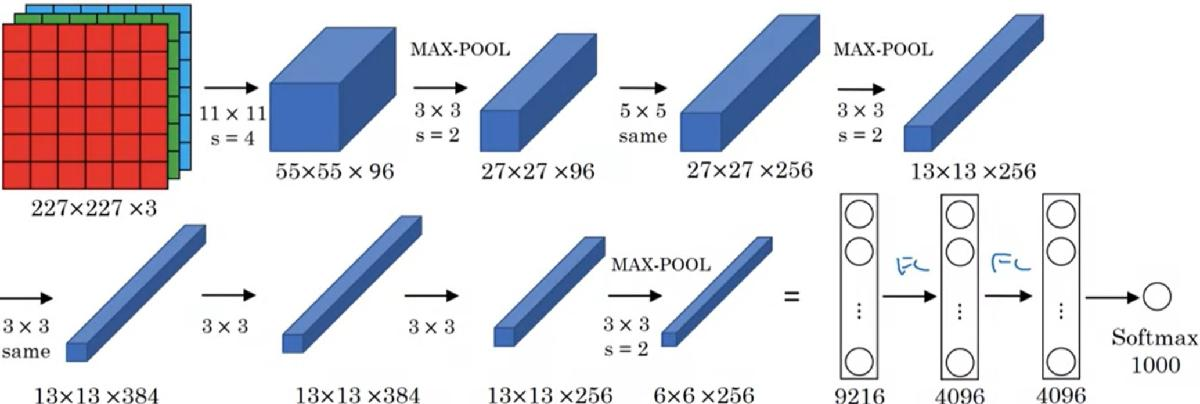

### Model input size

input_Size = alexnet_model.Layers(1).InputSize;

### Resize Image to match the input size

aug_train = augmentedImageDatastore(input_Size(1:2),x_train_ds);
aug_test = augmentedImageDatastore(input_Size(1:2),x_test_ds);

### Train and Test labels

y_train = double(categorical(x_train_ds.Labels));
y_test = double(categorical(x_test_ds.Labels));

### Extract Feature from images

layer = 'relu6';
feature_train = activations(alexnet_model,aug_train,layer,'OutputAs','rows');
feature_test = activations(alexnet_model,aug_test,layer,'OutputAs','rows');

### Pass Extracted features to SVM classifier

classifier = fitcecoc(feature_train,y_train);

# Result

### Do prediction

y_predicted = predict(classifier,feature_test);

### Accuracy

accuracy = mean(y_predicted == y_test)

accuracy = 0.8897

### Confusion Matrix

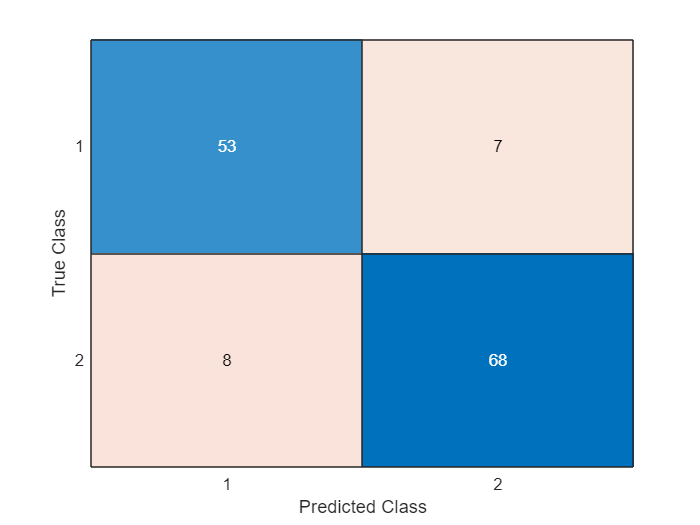

confusionchart(y_test,y_predicted)


[conf_matrix,order] = confusionmat(y_test,y_predicted)

conf_matrix =     53     7
     8    68


order =      1
     2


tp = conf_matrix(1,1)

tp = 53

tn = conf_matrix(2,2)

tn = 68

fn = conf_matrix(1,2)

fn = 7

fp = conf_matrix(2,1)

fp = 8

### Sensitivity

sensitivity = tp/(tp+fn)

sensitivity = 0.8833

### Specificity

specificity = tn/(tn+fp)

specificity = 0.8947

# RIM-ONE-DL

### Load Dataset

rimone_dl_data_store_train = imageDatastore('C:\gyani\Projects_MS\code\dataset\RIM-ONE_DL_images\partitioned_randomly\training_set','IncludeSubfolders',true,'LabelSource','foldernames');
rimone_dl_data_store_test = imageDatastore('C:\gyani\Projects_MS\code\dataset\RIM-ONE_DL_images\partitioned_randomly\test_set','IncludeSubfolders',true,'LabelSource','foldernames');

### Resize Image to match the input size

rim_one_dl_aug_train = augmentedImageDatastore(input_Size(1:2),rimone_dl_data_store_train);
rim_one_dl_aug_test = augmentedImageDatastore(input_Size(1:2),rimone_dl_data_store_test);

### Train and Test labels

rimone_dl_y_train = double(categorical(rimone_dl_data_store_train.Labels));
rimone_dl_y_test = double(categorical(rimone_dl_data_store_test.Labels));

### Extract Feature from images

layer = 'relu6';
rimone_dl_feature_train = activations(alexnet_model,rim_one_dl_aug_train,layer,'OutputAs','rows');
rimone_dl_feature_test = activations(alexnet_model,rim_one_dl_aug_test,layer,'OutputAs','rows');
rimone_dl_classifier = fitcecoc(rimone_dl_feature_train,rimone_dl_y_train);

# Result

### Do prediction

rimone_dl_y_predicted = predict(rimone_dl_classifier,rimone_dl_feature_test);
rimone_dl_accuracy = mean(rimone_dl_y_predicted == rimone_dl_y_test)

rimone_dl_accuracy = 0.8904

### Confusion Matrix

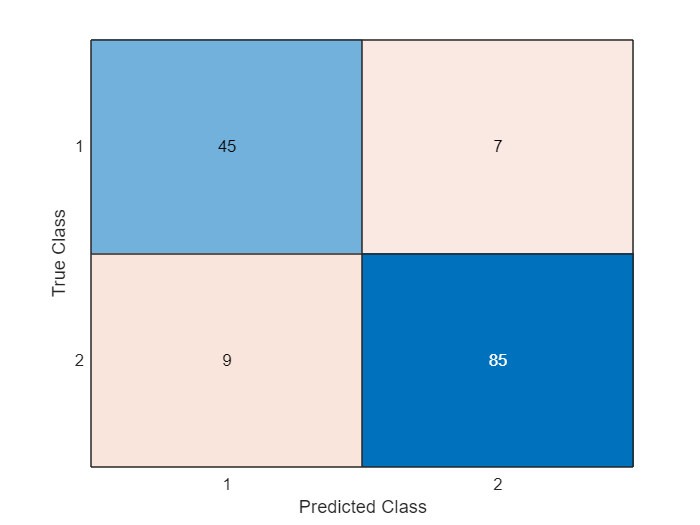

confusionchart(rimone_dl_y_test,rimone_dl_y_predicted)

[rimone_dl_conf_matrix,rimone_dl_order] = confusionmat(rimone_dl_y_test,rimone_dl_y_predicted)

rimone_dl_conf_matrix =     45     7
     9    85


rimone_dl_order =      1
     2


r1dl_tp = rimone_dl_conf_matrix(1,1)

r1dl_tp = 45

r1dl_tn = rimone_dl_conf_matrix(2,2)

r1dl_tn = 85

r1dl_fn = rimone_dl_conf_matrix(1,2)

r1dl_fn = 7

r1dl_fp = rimone_dl_conf_matrix(2,1)

r1dl_fp = 9

### Sensitivity

r1dl_sensitivity = r1dl_tp/(r1dl_tp+r1dl_fn)

r1dl_sensitivity = 0.8654

### Specificity

r1dl_specificity = r1dl_tn/(r1dl_tn+r1dl_fp)

r1dl_specificity = 0.9043

# ACRIMA Dataset

## **Load Dataset **

Load ACRIMA dataset and split it in train and test set. The split ration is 70:30


acrima_image_data_store = imageDatastore('C:\gyani\Projects_MS\code\dataset\ACRIMA_dataset\Database','IncludeSubfolders',true,'LabelSource','foldernames');

[acrima_x_train_ds,acrima_x_test_ds] = splitEachLabel(acrima_image_data_store,0.7,'randomized');

### Resize Image to match the input size

acrima_aug_train = augmentedImageDatastore(input_Size(1:2),acrima_x_train_ds);
acrima_aug_test = augmentedImageDatastore(input_Size(1:2),acrima_x_test_ds);

### Train and Test labels

acrima_y_train = double(categorical(acrima_x_train_ds.Labels));
acrima_y_test = double(categorical(acrima_x_test_ds.Labels));

### Extract Feature from images

layer = 'relu6';
acrima_feature_train = activations(alexnet_model,acrima_aug_train,layer,'OutputAs','rows');
acrima_feature_test = activations(alexnet_model,acrima_aug_test,layer,'OutputAs','rows');
acrima_classifier = fitcecoc(acrima_feature_train,acrima_y_train);

# Result

### Do prediction

acrima_y_predicted = predict(acrima_classifier,acrima_feature_test);
acrima_accuracy = mean(acrima_y_predicted == acrima_y_test)

acrima_accuracy = 0.9434

### Confusion Matrix

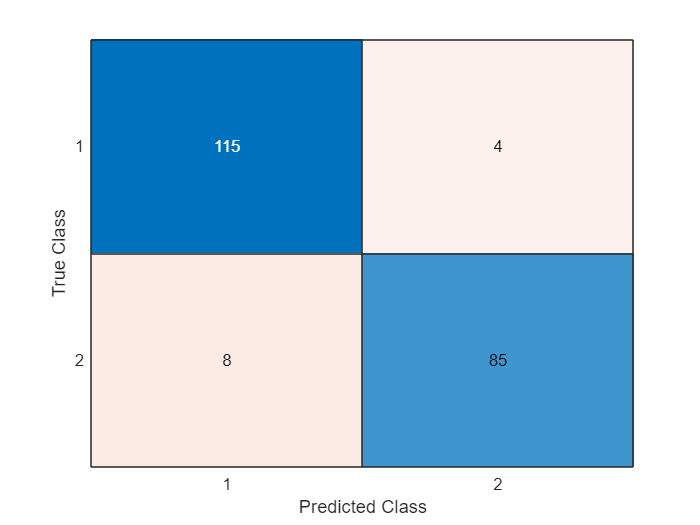

confusionchart(acrima_y_test,acrima_y_predicted)

[acrima_conf_matrix,acrima_order] = confusionmat(acrima_y_test,acrima_y_predicted)

acrima_conf_matrix =    115     4
     8    85


acrima_order =      1
     2


acrima_tp = acrima_conf_matrix(1,1)

acrima_tp = 115

acrima_tn = acrima_conf_matrix(2,2)

acrima_tn = 85

acrima_fn = acrima_conf_matrix(1,2)

acrima_fn = 4

acrima_fp = acrima_conf_matrix(2,1)

acrima_fp = 8

### Sensitivity

acrima_sensitivity = acrima_tp/(acrima_tp+acrima_fn)

acrima_sensitivity = 0.9664

### Specificity

acrima_specificity = acrima_tn/(acrima_tn+acrima_fp)

acrima_specificity = 0.9140

# Cross Dataset Prediction

#### RIMONE_V2_RIMONE_DL

RONE_r2_DL_y_predicted = predict(classifier,rimone_dl_feature_test);
RONE_r2_DL_accuracy = mean(RONE_r2_DL_y_predicted == rimone_dl_y_test)

RONE_r2_DL_accuracy = 0.8288

**RIMONE_V2_ACRIMA**

RONE_r2_ACRIMA_y_predicted = predict(classifier,acrima_feature_test);
RONE_r2_ACRIMA_accuracy = mean(RONE_r2_ACRIMA_y_predicted == acrima_y_test)

RONE_r2_ACRIMA_accuracy = 0.4953

#### RIMONE_DL_RIMONE_V2

RONE_DL_r2_y_predicted = predict(rimone_dl_classifier,feature_test);
RONE_DL_r2_accuracy = mean(RONE_DL_r2_y_predicted == y_test)

RONE_DL_r2_accuracy = 0.9044

#### RIMONE_DL_ACRIMA

RONE_DL_ACRIMA_y_predicted = predict(rimone_dl_classifier,acrima_feature_test);
RONE_DL_ACRIMA_accuracy = mean(RONE_DL_ACRIMA_y_predicted == acrima_y_test)

RONE_DL_ACRIMA_accuracy = 0.5755

**ACRIMA_RIMONE_V2**

ACRIMA_RONE_r2_y_predicted = predict(acrima_classifier,feature_test);
ACRIMA_RONE_r2_ACRIMA_accuracy = mean(ACRIMA_RONE_r2_y_predicted == y_test)

ACRIMA_RONE_r2_ACRIMA_accuracy = 0.4412

**ACRIMA_RIMONE_DL**

ACRIMA_RONE_dl_y_predicted = predict(acrima_classifier,rimone_dl_feature_test);
ACRIMA_RONE_dl_ACRIMA_accuracy = mean(ACRIMA_RONE_dl_y_predicted == rimone_dl_y_test)

ACRIMA_RONE_dl_ACRIMA_accuracy = 0.3973